% Sample data from a normal distribution
rng(42); % For reproducibility
data = normrnd(5, 2, 100, 1); % 100 samples from N(5, 2)

% Metropolis-Hastings MCMC algorithm to estimate mean (mu) and std (sigma)
numIterations = 5000; % Number of MCMC iterations
burnIn = 1000; % Number of burn-in samples to discard
mu_samples = zeros(numIterations, 1);
sigma_samples = zeros(numIterations, 1);

% Initial guesses
mu_current = mean(data);
sigma_current = std(data);

% Proposals
mu_proposal_std = 0.5;
sigma_proposal_std = 0.5;

% Likelihood function
likelihood = @(mu, sigma) sum(log(normpdf(data, mu, sigma)));

% Prior distributions (assuming vague priors)
prior_mu = @(mu) log(normpdf(mu, 0, 10)); % N(0, 10)
prior_sigma = @(sigma) log(gampdf(sigma, 1, 1)); % Gamma(1, 1)

% MCMC sampling
for i = 1:numIterations
    % Propose new mu and sigma
    mu_proposal = normrnd(mu_current, mu_proposal_std);
    sigma_proposal = abs(normrnd(sigma_current, sigma_proposal_std)); % sigma must be positive
    
    % Compute log-likelihoods
    log_likelihood_current = likelihood(mu_current, sigma_current);
    log_likelihood_proposal = likelihood(mu_proposal, sigma_proposal);
    
    % Compute log-priors
    log_prior_current = prior_mu(mu_current) + prior_sigma(sigma_current);
    log_prior_proposal = prior_mu(mu_proposal) + prior_sigma(sigma_proposal);
    
    % Compute acceptance ratio
    log_acceptance_ratio = (log_likelihood_proposal + log_prior_proposal) - ...
                           (log_likelihood_current + log_prior_current);
                       
    % Accept or reject
    if log(rand) < log_acceptance_ratio
        mu_current = mu_proposal;
        sigma_current = sigma_proposal;
    end
    
    % Store samples
    mu_samples(i) = mu_current;
    sigma_samples(i) = sigma_current;
end

% Discard burn-in samples
mu_samples = mu_samples(burnIn+1:end);
sigma_samples = sigma_samples(burnIn+1:end);

% Estimate parameters (posterior mean)
mu_estimate = mean(mu_samples);
sigma_estimate = mean(sigma_samples);

% Display results
fprintf('Estimated mean (mu): %.4f\n', mu_estimate);

Estimated mean (mu): 4.9003


fprintf('Estimated standard deviation (sigma): %.4f\n', sigma_estimate);

Estimated standard deviation (sigma): 2.0616


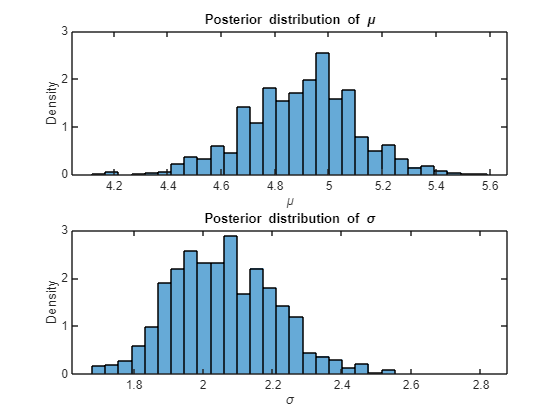


% Plot the results
figure;
subplot(2, 1, 1);
histogram(mu_samples, 30, 'Normalization', 'pdf');
title('Posterior distribution of \mu');
xlabel('\mu');
ylabel('Density');

subplot(2, 1, 2);
histogram(sigma_samples, 30, 'Normalization', 'pdf');
title('Posterior distribution of \sigma');
xlabel('\sigma');
ylabel('Density');